clear

temp=readmatrix('./data/loop100.csv');
loop100=zeros(40,21);
loop100(:,1)=temp(1:40,1);

for i=1:20
    loop100(:,i+1)=temp(40*(i-1)+1:40*i,2);
end

loop100(:,22)=mean(loop100(:,2:21),2);

disp(['Min loop runtime: ',num2str(min(temp(:,2))),'s'])

Min loop runtime: 0.245s


disp(['Min loop average runtime: ',num2str(min(loop100(:,22))),'s'])

Min loop average runtime: 0.2804s


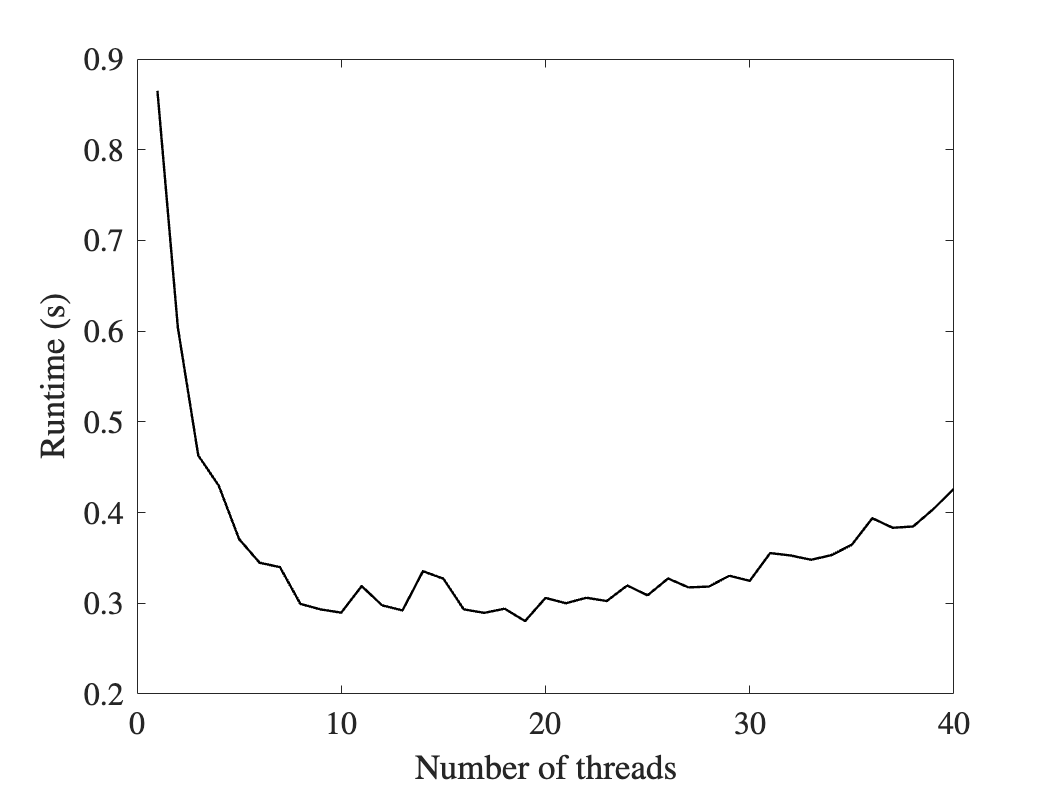


fig1 = figure;
plot(loop100(:,1),loop100(:,22),'k','LineWidth',1.2)
xlabel('Number of threads','interpreter','latex', 'FontSize', 16)
ylabel('Runtime (s)','interpreter','latex', 'FontSize', 16)
set(gca,'TickLabelInterpreter','latex', 'FontSize', 16)
%saveas(fig1,'loop100.eps')



temp=readmatrix('./data/blas100.csv');
blas100=zeros(40,21);
blas100(:,1)=temp(1:40,1);

for i=1:20
    blas100(:,i+1)=temp(40*(i-1)+1:40*i,2);
end

blas100(:,22)=mean(blas100(:,2:21),2);

disp(['Min blas runtime: ',num2str(min(temp(:,2))),'s'])

Min blas runtime: 0.734s


disp(['Min blas average runtime: ',num2str(min(loop100(:,22))),'s'])

Min blas average runtime: 0.2804s


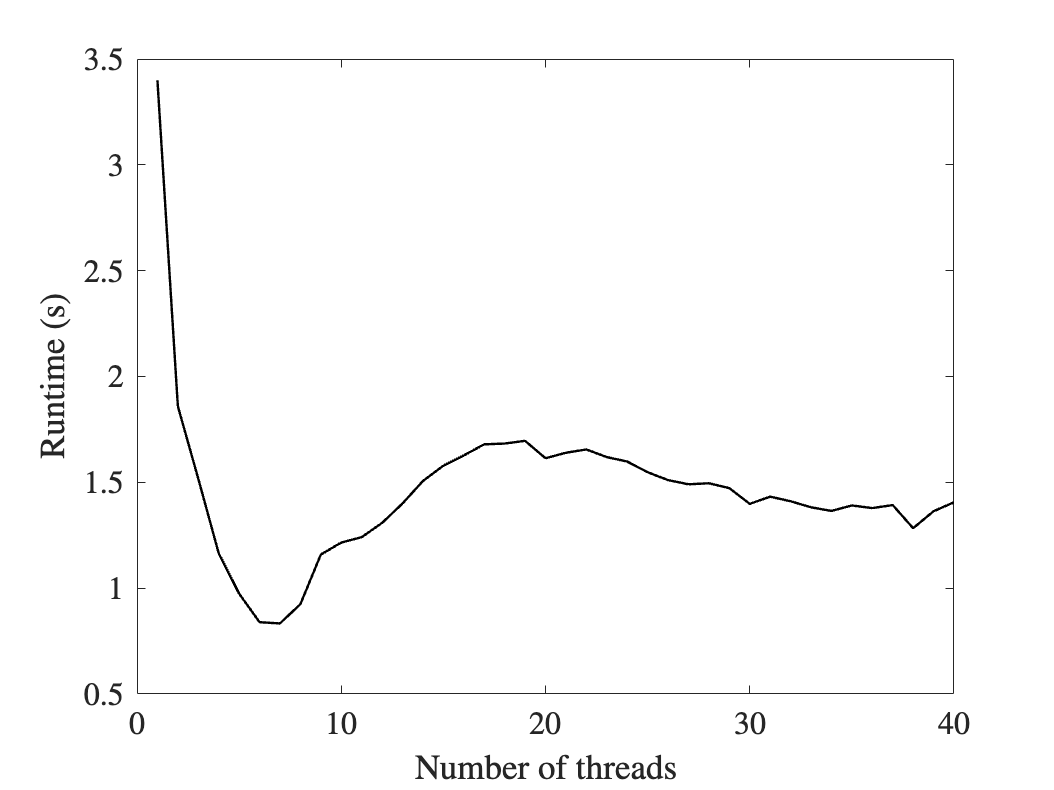


fig2 = figure;
plot(blas100(:,1),blas100(:,22),'k','LineWidth',1.2)
xlabel('Number of threads','interpreter','latex', 'FontSize', 16)
ylabel('Runtime (s)','interpreter','latex', 'FontSize', 16)
set(gca,'TickLabelInterpreter','latex', 'FontSize', 16)
%saveas(fig2,'blas100.eps')



temp=readmatrix('./data/loop1000.csv');
loop1000=zeros(40,21);
loop1000(:,1)=temp(1:40,1);

for i=1:20
    loop1000(:,i+1)=temp(40*(i-1)+1:40*i,2);
end

loop1000(:,22)=mean(loop1000(:,2:21),2);

disp(['Min loop runtime (1000 by 1000): ',num2str(min(temp(:,2))),'s'])

Min loop runtime (1000 by 1000): 15.817s


disp(['Min loop average runtime (1000 by 1000): ',num2str(min(loop1000(:,22))),'s'])

Min loop average runtime (1000 by 1000): 18.7745s


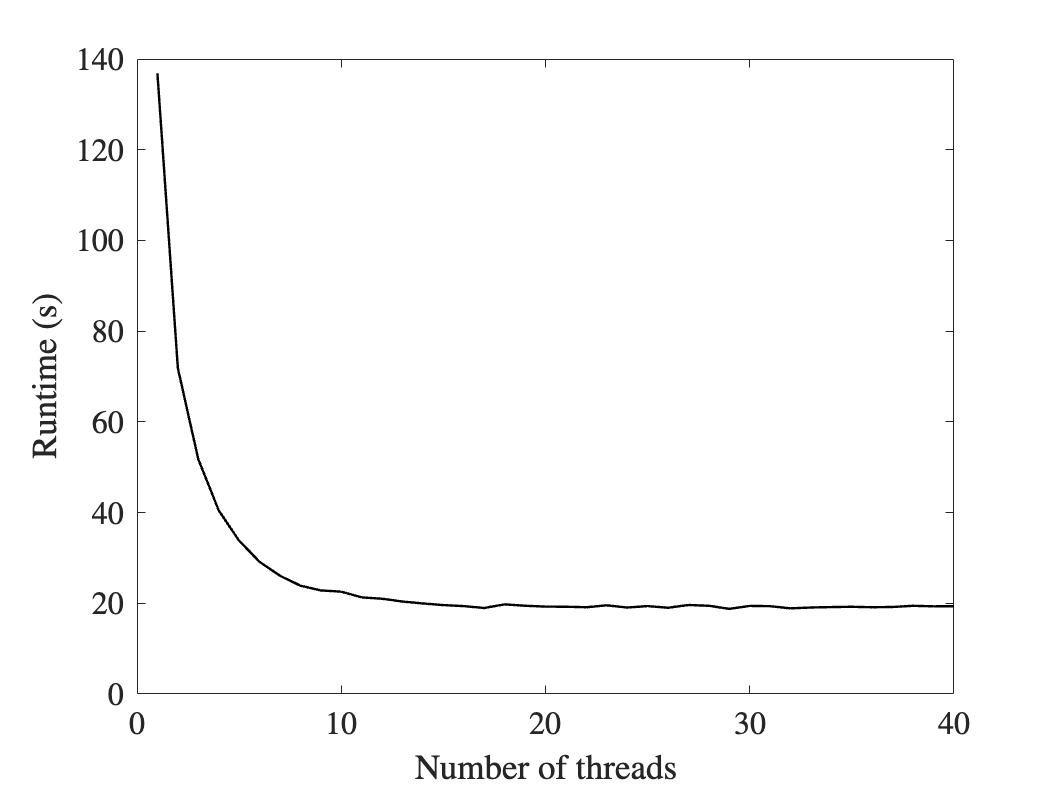


fig3 = figure;
plot(loop1000(:,1),loop1000(:,22),'k','LineWidth',1.2)
xlabel('Number of threads','interpreter','latex', 'FontSize', 16)
ylabel('Runtime (s)','interpreter','latex', 'FontSize', 16)
set(gca,'TickLabelInterpreter','latex', 'FontSize', 16)
%saveas(fig3,'loop1000.eps')